% TODO:
% 1. have way of passing generate_H cell, and then just load all of those
%    patterns simulateously in 1 go instead of as separate runs
%
% ---- PATH -----
% Matlab uses startup.m to run startup code...
% Put this in your startup.m so that the code for this is in path:
%
% addpath(genpath('/Volumes/MATLAB-Drive/')) % or wherever your CODE files are
% located
% addpath(genpath('~/Data/Raw/')) % or wherever your DATA files are located

% ===================================================
% OPTION STRUCT encoding properties of the script run
% ===================================================
% see +option.default() to set default options
if ~exist('Option','var')
    Option = option.defaults();
else
    Option = option.setdefaults(Option);
end

Option.numPartition = 2;
Option.positiveDerivativeCheck = [0 0.01];
Option.generateH = "fromFilteredEEG  fromRipTimes";

%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("Running with Option struct => ")
disp(Option);

%%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("------------------------")
disp("    Obtaining events    ")
disp("------------------------")
Events = events.ThetaDeltaRipple(Option);

## ACQUIRE SPIKES 

disp("------------------------")
disp("    Getting spikes      ")
disp("------------------------")
Spk = spikes.getSpikeTrain(Option.animal, Option.spikeBinSize, ...
    Option.samplingRate);

% filter the neurons whose firing rate is lower than specified threshold
if Option.preProcess_FilterLowFR
    disp("------------------------")
    disp("Filtering low FR neurons")
    disp("------------------------")
    Spk = trialSpikes.filterFR(Spk, 0.1);
    disp("Mean FR: " + sort(Spk.avgFR))
end

if Option.preProcess_gaussianFilter
    % Gaussian filter the spikeCountMatrix/spikeRateMatrix
    gauss = gausswin(Option.preProcess_gaussianFilter);
    for i = progress(1:size(Spk.spikeRateMatrix, 1), 'Title', 'Gaussian filtering')
        Spk.spikeRateMatrix(i, :)  = conv(Spk.spikeRateMatrix(i, :), gauss, 'same');
        Spk.spikeCountMatrix(i, :) = conv(Spk.spikeCountMatrix(i, :), gauss, 'same');
    end
end

if Option.preProcess_zscore
    % Z-score the spikeCountMatrix/spikeRateMatrix
    disp(" Z-scoring ")
    Spk.spikeRateMatrix  = zscore(Spk.spikeRateMatrix,  0, 2);
    Spk.spikeCountMatrix = zscore(Spk.spikeCountMatrix, 0, 2);
    Spk.avgFR = mean(Spk.spikeRateMatrix, 2);
end
prewindow_copy = Spk;


%%%%%%%%%%%%%%%% OBTAIN BEHAVIOR TABLE    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("------------------------")
disp("    Obtaining Behaviors    ")
disp("------------------------")
running_times = Spk.timeBinMidPoints(Spk.sessionTypePerBin == 1);
[Behaviors, thrown_out_times] = table.behavior.lookup(Option.animal, ...
        running_times);

Behaviors

Quantiles

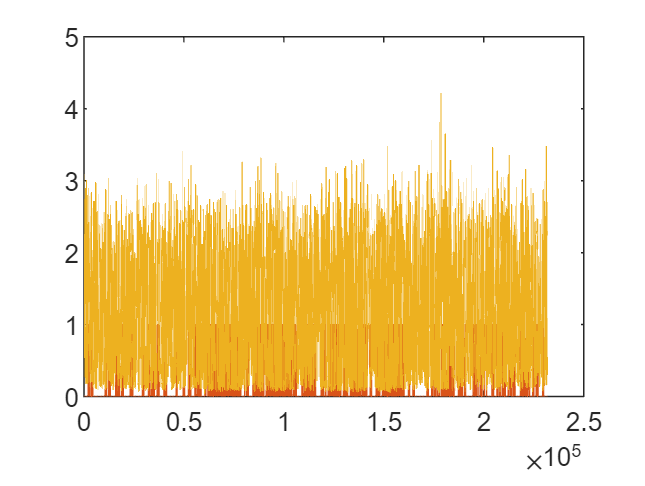

plot(Events.H)

Rhythms Identification

% Rhythms: 1*4/1*5 cell
Rhythms = cell(1,4);
Rhythms{1,4} = ["theta", "delta", "ripple"];

for i = 1:size(Events.H, 2)
    idx = ~isnan(Events.H(:, i));    
    time_points = Events.times(idx); 
    Rhythms{1,i} = time_points;
end


% Pre-allocate a 3D cell array to store spike count matrix samples
% spike_counts = [trajbound, lindist_bin, rhythm_pattern]
% traj: 0/1 for outbound/inbound
% lindist_bin: 0-20
% rhythm_pattern: theta, delta, ripple, universe(optional, we use universe here)

areaPerNeuron = load("areaPerNeuron.mat");
% Identify unique brain areas
unique_areas = unique(areaPerNeuron.areaPerNeuron);
% Initialize a struct to hold a cell array for each brain area
spike_counts_by_area = struct();
% Loop over unique brain areas
for a = 1:length(unique_areas)
    disp(unique_areas(a))
    % Initialize a 2D cell array for this brain area
    emptyStruct = struct('val',[],'time',[]);
    spike_counts_by_area.(unique_areas{a}) = cellfun(@(x) emptyStruct, cell(2, 30), 'UniformOutput', false);
    % Find rows of the spike count matrix corresponding to this brain area
    area_rows = find(areaPerNeuron.areaPerNeuron == unique_areas{a});
    % Loop over rows of the spike count matrix for this brain area
    for i = area_rows'
        % Loop over all time bins
        for j = 1:length(Spk.timeBinStartEnd) - 1
            % Find indices in 'behavior' where 'time' falls within this time bin
            idx = find(Behaviors.time >= Spk.timeBinStartEnd(j) & Behaviors.time < Spk.timeBinStartEnd(j + 1) & abs(Behaviors.vel) > 5);
            % Extract corresponding 'lindist' bin indices
            lindist_bin_idx = discretize(Behaviors.lindist(idx), linspace(min(Behaviors.lindist), max(Behaviors.lindist), 31));
            % Extract corresponding 'trajbound' indices
            trajbound_idx = Behaviors.trajbound(idx) + 1; % assuming trajbound is 0/1 for outbound/inbound
            % For each unique combination of 'lindist' bin and 'trajbound' indices, append the spike count to the corresponding cell
            for k = 1:length(lindist_bin_idx)
                if ~isnan(lindist_bin_idx(k)) % checking for nan values
                    spike_counts_by_area.(unique_areas{a}){trajbound_idx(k), lindist_bin_idx(k)}.val = ...
                        [spike_counts_by_area.(unique_areas{a}){trajbound_idx(k), lindist_bin_idx(k)}.val; Spk.spikeCountMatrix(i, j)'];
                    spike_counts_by_area.(unique_areas{a}){trajbound_idx(k), lindist_bin_idx(k)}.time = ...
                        [spike_counts_by_area.(unique_areas{a}){trajbound_idx(k), lindist_bin_idx(k)}.time; Behaviors.time(idx(k))];
                end
            end
            disp(j)
        end
    end
end


JPECC

warning('off','all')
%when comparing two cells, first sampling one based on time to reach equal length
disp("------------------------")
disp("        jpecc           ")
disp("------------------------")

Option.analysis.JPECC = 1;

if Option.analysis.JPECC
    Option.threshold = [0 60];
    Jpecc_Results = analysis.JPECC_task2(spike_counts_by_area.CA1, spike_counts_by_area.PFC, 1, Patterns_overall, Option);
    Option.threshold = [-60 0];
    Jpecc_Results2 = analysis.JPECC_task2(spike_counts_by_area.CA1, spike_counts_by_area.PFC, 1, Patterns_overall, Option);
end

Jpecc_Results2.jpecc

conditions = {'single', 'combined'};
categories = {'overall', 'theta', 'delta', 'ripple'};
sessions = {'HPCafterPFC', 'PFCafterHPC'};
results = {Jpecc_Results, Jpecc_Results2};

Heatmap = struct();

for sessIdx = 1:length(sessions)
    session = sessions{sessIdx};
    result = results{sessIdx};
    
    for condIdx = 1:length(conditions)
        condition = conditions{condIdx};
        
        for catIdx = 1:length(categories)
            category = categories{catIdx};
            
            if strcmp(category, 'overall')
                fieldName = ['r', condition]; % Special case for 'overall'
            else
                fieldName = [category, '_', condition];
            end
            
            [SM, Single] = stackAndAverageMatrices(result.jpecc, fieldName, 3, 30);
            Heatmap.(condition).(category).(session).Mean = Single;
            Heatmap.(condition).(category).(session).stackedmatrices = SM;
        end
    end
end


Generate Gaussian Filter

sigma = 0.7;
filter_size = 2;
[x, y] = meshgrid(-filter_size:filter_size, -filter_size:filter_size);
h = exp(-(x.^2 + y.^2) / (2 * sigma^2));
h = h / sum(h(:));  % normalize the filter

Heatmap Version 1 (Blue-White-Red)

lindist_trajbound = meanMatrix;
lindist_trajbound = conv2(meanMatrix, h, 'same');

% heatmap
figure;
pcolor(lindist_trajbound);
%shading interp;

colormap(flipud(brewermap(64,'RdBu')));
caxis([-0.2 0.2]);
colorbar;


xlabel('PFC');
ylabel('HPC');
title('lindist-trajbound: HPC after PFC');

xline(21,"Color",[1,1,1],"LineWidth",2, "Alpha",1)
yline(21,"Color",[1,1,1],"LineWidth",2, "Alpha",1)
line([1 40], [1 40], 'Color', [1,1,1], 'LineWidth', 1,"LineStyle", "--");
line([1 20], [21 40], 'Color', [1,1,1], 'LineWidth', 1,"LineStyle", "--");
line([21 40], [1 20], 'Color', [1,1,1], 'LineWidth', 1,"LineStyle", "--");

range = [1 20];
one_third_x = range(1) + (range(2) - range(1)) / 3;
one_third_y = range(1) + (range(2) - range(1)) / 3;
hold on
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
one_third_x = range(2) - (range(2) - range(1)) / 3;
one_third_y = range(2) - (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
range = [21 40];
one_third_x = range(1) + (range(2) - range(1)) / 3;
one_third_y = range(1) + (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
one_third_x = range(2) - (range(2) - range(1)) / 3;
one_third_y = range(2) - (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
%text(one_third_x, one_third_y, '1/3', 'Color', 'k');

Heatmap Version 2

% 创建一个颜色矩阵
n = 256; % 颜色的数量

% 定义橙黄色和天蓝色
orange_yellow = [1, 0.7, 0];
sky_blue = [0.5, 0.75, 1];

% 创建颜色矩阵
r = [linspace(orange_yellow(1), 1, n/4)'; linspace(1, 0, 6*n/8)'; linspace(0, 0.4, 6*n/8)'; linspace(0.4, sky_blue(1), n/4)'];
g = [linspace(orange_yellow(2), 0.13, n/4)'; linspace(0, 0, 6*n/8)'; linspace(0, 0.5, 6*n/8)'; linspace(0.5, sky_blue(2), n/4)'];
b = [linspace(orange_yellow(3), 0, n/4)'; linspace(0, 0, 6*n/8)'; linspace(0, 1, 6*n/8)'; linspace(1, sky_blue(3), n/4)'];

cmap = [r, g, b];
cmap = flipud(cmap.^1.1)

cmap =     0.4665    0.7287    1.0000
    0.4649    0.7245    1.0000
    0.4633    0.7203    1.0000
    0.4616    0.7160    1.0000
    0.4600    0.7118    1.0000
    0.4584    0.7076    1.0000
    0.4568    0.7033    1.0000
    0.4551    0.6991    1.0000
    0.4535    0.6949    1.0000
    0.4519    0.6907    1.0000


%{
lindist_trajbound2 = Single{1,1};
lindist_trajbound2 = conv2(lindist_trajbound2, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound2);
%shading interp;

%{
caxis([-0.3 0.4]*0.8);
cmocean('tarn','pivot',0,'negative')
colorbar
%}

caxis([-0.25 0.25]);
colormap(cmap);
colorbar;


set(t, 'EdgeColor', 'none');

xlabel('PFC');
ylabel('HPC');
title('lindist-trajbound: HPC after PFC');

xline(21,"Color",[1,1,1],"LineWidth",2, "Alpha",0.7)
yline(21,"Color",[1,1,1],"LineWidth",2, "Alpha",0.7)
line([1 40], [1 40], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");
%line([1 20], [21 40], 'Color', [1,1,1], 'LineWidth', 1,"LineStyle", "--");
%line([21 40], [1 20], 'Color', [1,1,1], 'LineWidth', 1,"LineStyle", "--");

range = [1 20];
one_third_x = range(1) + (range(2) - range(1)) / 3;
one_third_y = range(1) + (range(2) - range(1)) / 3;
hold on
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
one_third_x = range(2) - (range(2) - range(1)) / 3;
one_third_y = range(2) - (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
range = [21 40];
one_third_x = range(1) + (range(2) - range(1)) / 3;
one_third_y = range(1) + (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
one_third_x = range(2) - (range(2) - range(1)) / 3;
one_third_y = range(2) - (range(2) - range(1)) / 3;
plot(one_third_x, one_third_y, 'w*', 'LineWidth', 3);
%text(one_third_x, one_third_y, '1/3', 'Color', 'k');
%}

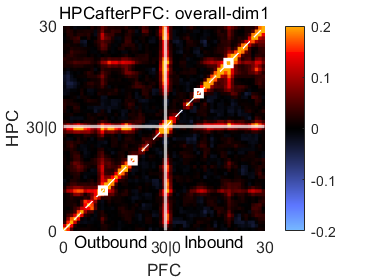

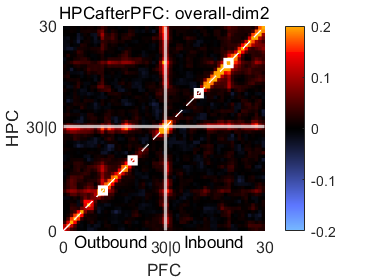

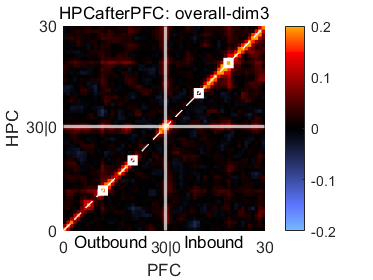

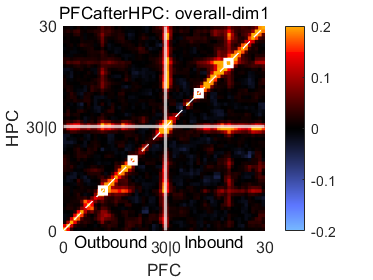

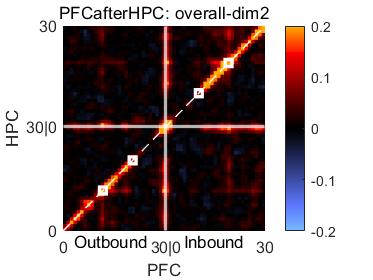

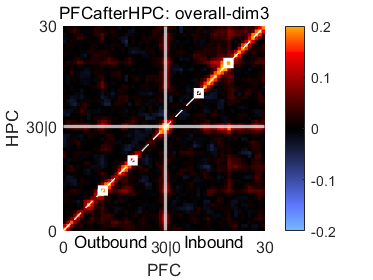

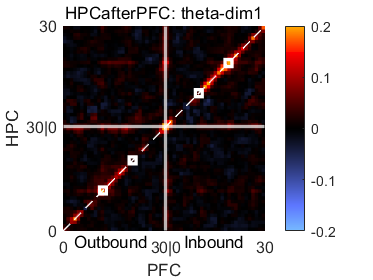

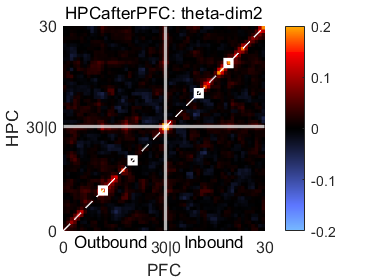

conditions = {'single', 'combined'};
categories = {'overall', 'theta', 'delta', 'ripple'};
sessions = {'HPCafterPFC', 'PFCafterHPC'};
save_folder = 'F:\ComSub\Figures\2';


for condIdx = 1:length(conditions)
    condition = conditions{condIdx};
    
    for catIdx = 1:length(categories)
        category = categories{catIdx};
        
        for sessIdx = 1:length(sessions)
            session = sessions{sessIdx};
            
            Single = Heatmap.(condition).(category).(session).Mean;
            plotAndSave(Single, h, cmap, session, category, condition, save_folder);
        end
    end
end


M = lindist_trajbound;
M2 = lindist_trajbound2;

A = triu(M, 1);
B = tril(M, -1);
C = triu(M2, 1);
D = tril(M2, -1);

diag_elements = diag(M);
diag_elements(:) = 1;

A = flipud((A + diag(diag_elements))')
B = flipud(B + diag(diag_elements))
C = flipud(C + diag(diag_elements))
D = flipud((D + diag(diag_elements))')

result = (A-B) + (C-D)

%result(isinf(result) | isnan(result)) = 0;  % 例如，将 Inf 和 NaN 替换为 0

result = conv2(result, h, 'same');
% heatmap
figure;
t = pcolor(result);
set(t, "EdgeColor", "none")
%shading interp;

%colormap(flipud(brewermap(32,'Blues')));
caxis([-0.2 0.2]);
cmocean('curl')
colorbar;



Utils

function [stackedMatrices, M_Type] = stackAndAverageMatrices(jpecc,type,row,col)
    stackedMatrices = cell(row, col);
    M_Type = cell(1,row);

    for j = 1:row
        for i = 1:col
            x = nd.fieldGet(jpecc, type);
            stackedMatrices{j,i} = cell2mat(x(:,:,j,i));
        end
        stackedMatrice = cat(col, stackedMatrices{j,:});
        meanMatrix = nanmean(stackedMatrice, col);
        M_Type{1,j} = meanMatrix;
    end
end

function plotAndSave(Single, h, cmap, session, category, condition, save_folder)
    for i = 1:length(Single)
        if i == 1 && strcmp(condition, 'combined')
            continue; % 跳过top 1 dims
        end
        
        lindist_trajbound = Single{1,i};
        lindist_trajbound = conv2(lindist_trajbound, h, 'same');

        % heatmap
        figure;
        t = pcolor(lindist_trajbound);
        caxis([-0.2 0.2]);
        colormap(cmap);
        colorbar;
        set(t, 'EdgeColor', 'none');
        xlabel('PFC');
        ylabel('HPC');

        % 设置坐标轴刻度
        xticks([1, 31, 60]);
        yticks([1, 31, 60]);

        % 设置x和y轴的刻度标签
        xticklabels({'0', '30|0', '30'});
        yticklabels({'0', '30|0', '30'});

        % 添加额外的标签
        text(15, -2, 'Outbound', 'HorizontalAlignment', 'center');
        text(45, -2, 'Inbound', 'HorizontalAlignment', 'center');
        
        % ... 其他代码 ...
        if strcmp(condition, 'combined')
            title_str = [session ': ' category '-top ' num2str(i) ' dims'];
            filename_str = [save_folder '\' session '_' category '_top_' num2str(i) '_dims.png'];
        else
            title_str = [session ': ' category '-dim' num2str(i)];
            filename_str = [save_folder '\' session '_' category '_dim' num2str(i) '.png'];
        end
        
        title(title_str);

        xline(31,"Color",[1,1,1],"LineWidth",2, "Alpha",0.7)
        yline(31,"Color",[1,1,1],"LineWidth",2, "Alpha",0.7)
        line([1 60], [1 60], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");
        
        
        range = [1 30];
        one_third_x = range(1) + (range(2) - range(1)) / 3;
        one_third_y = range(1) + (range(2) - range(1)) / 3;
        hold on
        rectangle('Position', [one_third_x+1, one_third_y+1, 2, 2], 'EdgeColor', 'w', 'LineWidth', 2);
        one_third_x = range(2) - (range(2) - range(1)) / 3;
        one_third_y = range(2) - (range(2) - range(1)) / 3;
        rectangle('Position', [one_third_x, one_third_y, 2, 2], 'EdgeColor', 'w', 'LineWidth', 2);
        range = [31 60];
        one_third_x = range(1) + (range(2) - range(1)) / 3;
        one_third_y = range(1) + (range(2) - range(1)) / 3;
        rectangle('Position', [one_third_x-1, one_third_y-1, 2, 2], 'EdgeColor', 'w', 'LineWidth', 2);
        one_third_x = range(2) - (range(2) - range(1)) / 3;
        one_third_y = range(2) - (range(2) - range(1)) / 3;
        rectangle('Position', [one_third_x-2, one_third_y-2, 2, 2], 'EdgeColor', 'w', 'LineWidth', 2);
        
        % 保存图像
        saveas(gcf, filename_str);
    end
end




